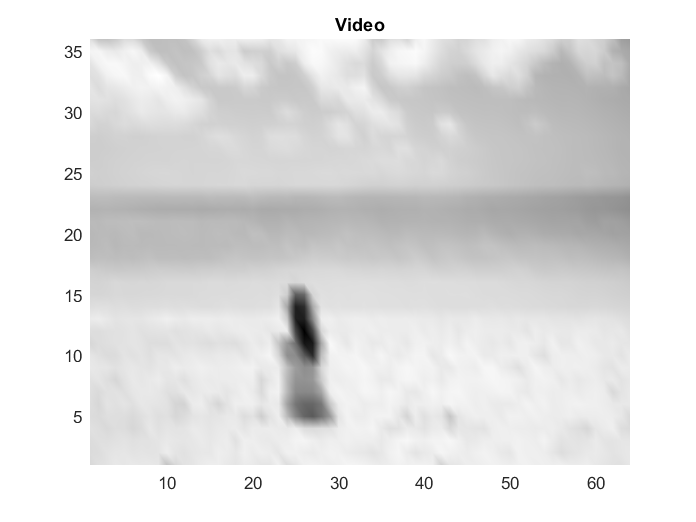

close all
clear all
clc

test=[' Test 1 '];

%video display
vid=read(VideoReader('C:\Users\saira\OneDrive\Desktop\RAG\5TH SEMESTER\MIS-5\ENDPROJECT\BACKGROUND_SEPERATION\VIDEO_3.mp4'));
vid=vid(:,:,:,1:2:end);
frame=size(vid);
res=[frame(1), frame(2)]/10;
frame=frame(4);
dt=12/frame;
for i=[1:frame]
video(:,:,i)=imresize(flipud(double(rgb2gray(vid(:,:,:,i)))), res);
end


figure
for i=[1:frame]
pcolor(video(:,:,i)), colormap(gray), shading interp
pause(dt)
end
title(['Video'])




%% Construct X and X'

X=[];
for i=[1:frame-1]
dum=video(:,:,i);
X=[X, dum(:)];
end
X

X =   153.8321  153.3670  153.1418  153.4138  153.2676  153.4795  152.7697  153.5023  155.1319  156.3429  158.0833  158.5441  158.8971  160.4460  160.5307  161.5342  162.1786  162.9193  165.3411  166.0532  167.9102  168.7350  169.8274  170.7163  172.3534  172.9568  174.6804  174.7122  176.3614  177.1999  178.1821  177.3561  177.7154  177.1845  176.5173  174.8328  174.0741  171.6805  169.1848  166.1408  164.3985  162.2546  159.3865  157.2657  155.7217  152.7748  149.8768  148.2084  147.1276  145.2015
  165.3030  164.6758  163.9732  163.4851  162.8593  162.7454  162.2465  162.5320  161.1579  161.5584  160.3698  160.4032  160.1399  161.0181  161.0038  161.4271  162.4794  162.4048  163.1510  163.1779  164.4380  164.6647  165.6107  165.8069  166.1951  167.6712  168.8975  169.6312  171.6349  173.3894  174.9008  175.8128  176.6413  177.2801  178.5893  178.9939  179.4576  179.2275  179.8426  180.7788  181.2419  181.0366  180.9561  180.9697  180.1158  179.7233  179.7235  179.0748  178.2541  178


X_tild=[];
for i=[2:frame]
dum=video(:,:,i);
X_tild=[X_tild, dum(:)];
end
X_tild

X_tild =   153.3670  153.1418  153.4138  153.2676  153.4795  152.7697  153.5023  155.1319  156.3429  158.0833  158.5441  158.8971  160.4460  160.5307  161.5342  162.1786  162.9193  165.3411  166.0532  167.9102  168.7350  169.8274  170.7163  172.3534  172.9568  174.6804  174.7122  176.3614  177.1999  178.1821  177.3561  177.7154  177.1845  176.5173  174.8328  174.0741  171.6805  169.1848  166.1408  164.3985  162.2546  159.3865  157.2657  155.7217  152.7748  149.8768  148.2084  147.1276  145.2015  145.4863
  164.6758  163.9732  163.4851  162.8593  162.7454  162.2465  162.5320  161.1579  161.5584  160.3698  160.4032  160.1399  161.0181  161.0038  161.4271  162.4794  162.4048  163.1510  163.1779  164.4380  164.6647  165.6107  165.8069  166.1951  167.6712  168.8975  169.6312  171.6349  173.3894  174.9008  175.8128  176.6413  177.2801  178.5893  178.9939  179.4576  179.2275  179.8426  180.7788  181.2419  181.0366  180.9561  180.9697  180.1158  179.7233  179.7235  179.0748  178.2541  178.2235

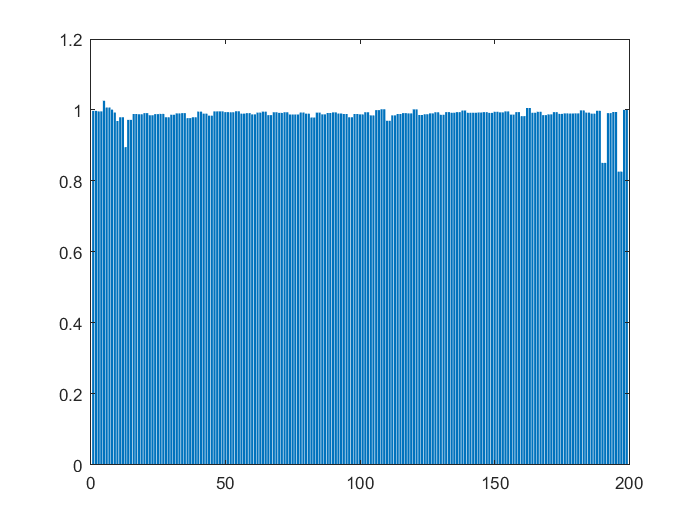





%% DMD

[U, S, V]=svd(X, 'econ');
A_tild=(U')*X_tild*V*inv(S);
[W,D]=eig(A_tild);
phi=U*W;



%% Reconstruct Video
bar(abs(diag(D)))
dum=diag(D);
Omega=zeros(size(D));
for i=[1:frame-1]
Omega(i,i)=log(dum(i));
Omega(i,i)=Omega(i,i)/(dt);
end

b=phi\X(:,1);
t=(1:frame);
X_recon_whole=[];

for i=[1:frame-1]
X_recon_whole=[X_recon_whole, phi*D.^i*b];
end

%% Play Reconstructed Video 
figure
for i=[1:frame-1]
dum=abs(reshape(X_recon_whole(:,i), res));
pcolor(dum), colormap(gray), shading interp
pause(dt)
end

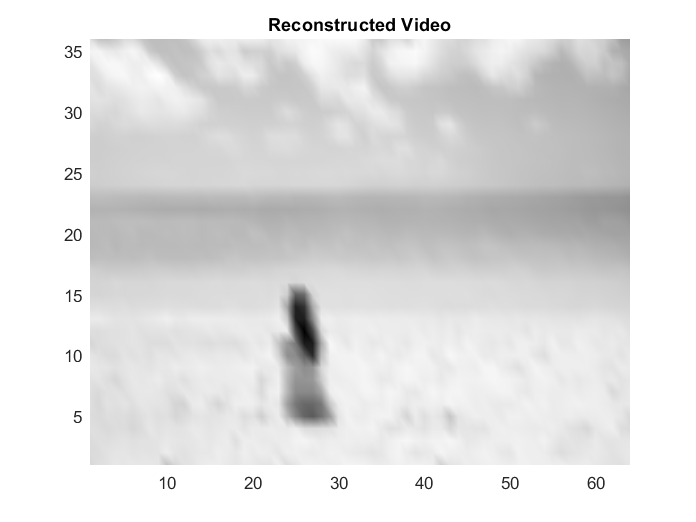

title(['Reconstructed Video'])

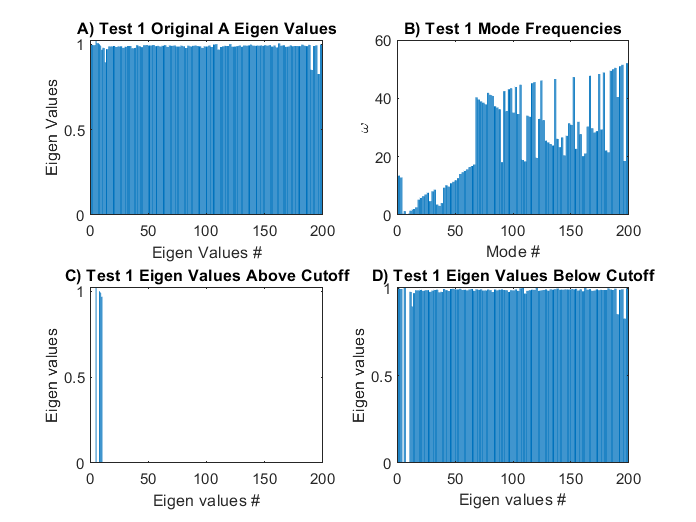



figure
subplot(2,2,1)
bar(abs(diag(D)))
title(['A)', test, 'Original A Eigen Values'])
ylabel('Eigen Values'); xlabel('Eigen Values #'); 
hold on

subplot(2,2,2)
bar(abs(diag(Omega)))
title(['B)', test, 'Mode Frequencies'])
ylabel('\omega'); xlabel('Mode #');  
hold on

low_cutoff=1;
D_low=D;
D_low(abs(Omega) > low_cutoff)=0;

subplot(2,2,3);
bar(abs(diag(D_low)))
title(['C)', test, 'Eigen Values Above Cutoff'])
ylabel('Eigen values'); xlabel('Eigen values #'); 
hold on 


high_cutoff=1;
D_high=D;
D_high(abs(Omega) <= high_cutoff)=0;

subplot(2,2,4);
bar(abs(diag(D_high)))
title(['D)', test, 'Eigen Values Below Cutoff'])
ylabel('Eigen values'); xlabel('Eigen values #'); 
hold on

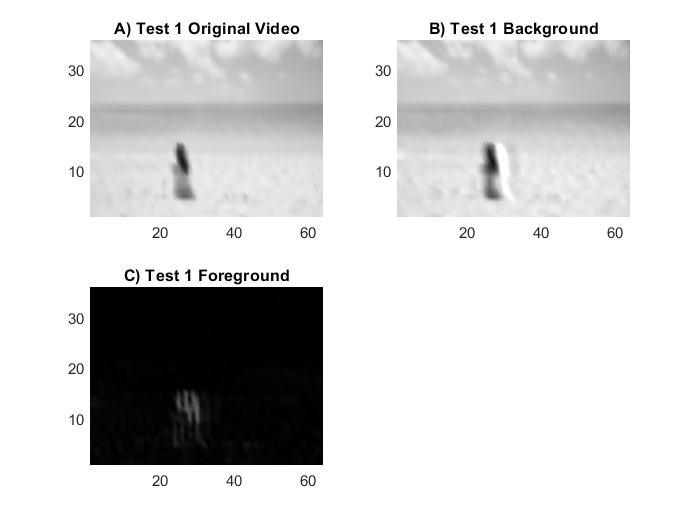



%% Reconstruct Video
X_recon_back=[];
for i=[1:frame-1]
X_recon_back=[X_recon_back, phi*D_low.^i*b];
end

X_recon_fore=[];
for i=[1:frame-1]
X_recon_fore=[X_recon_fore, phi*D_high.^i*b];
end


%% View Original/Background/Foreground
figure
for i=[1:frame-1]

dum1=abs(reshape(X_recon_whole(:,i), res));
subplot(2,2,1)
pcolor(dum1), colormap(gray), shading interp
caxis([0, 255]);
title(['A)', test, 'Original Video'])

dum2=abs(reshape(X_recon_back(:,i), res));
subplot(2,2,2)
pcolor(dum2), colormap(gray), shading interp
caxis([0, 255]);
title(['B)', test, 'Background'])

dum3=abs(reshape(X_recon_fore(:,i), res));
subplot(2,2,3)
pcolor(dum3), colormap(gray), shading interp
caxis([0, 255]);
title(['C)', test, 'Foreground'])

pause(0.01)
end